# Estimating `k`, The Complexity of the Noise Model

load 'quad_copter_models.mat';

InnerReferenceModel = mk_2nd_order(12, .6);
InnerReferenceModel_dt = c2d(InnerReferenceModel, Ts);

We now use VRFT to generate a controller for every value of `k` in the range we are considering. The controllers will be used to evaluate the closed loop step response of the system. 

Note: In the VRFT we consider the Mixer and the PitchRateModel as a single model: the PlantModel. We can do this because we have calculated $dM$from the input data.

% we consider ARX models of orders 1 to 15

bode_bw = { 10E-1, 10E3 };
k_range = 1:15;

ModelInfo = struct();

for k = k_range;
    ModelInfo(k).NoiseOrder = k; 
    ModelInfo(k).Controller = VRFT1_ry(vrft_data.dM, vrft_data.q_dot, ...
        InnerReferenceModel_dt, PIDControllerClass_dt, [], k, []);
    
    cloop = loopsens(PlantModel_dt, ModelInfo(k).Controller);
    ModelInfo(k).ComplSens = minreal(cloop.Ti);
    
    myStepInfo = stepinfo(ModelInfo(k).ComplSens);
    ModelInfo(k).StepOvershootPercent = myStepInfo.Overshoot;
    ModelInfo(k).SettlingTime = myStepInfo.SettlingTime;
    
    ModelInfo(k).ComplSensZeros = zero(ModelInfo(k).ComplSens); 
    ModelInfo(k).HasUnstableZeros = min(sum(abs(ModelInfo(k).ComplSensZeros) > 1), 1);
end

Raw Results:


    NoiseOrder    Controller    ComplSens    StepOvershootPercent    SettlingTime    ComplSensZeros    HasUnstableZeros
    __________    __________    _________    ____________________    ____________    ______________    ________________
     1            [1x1 tf]      [1x1 ss]     31.4639386346451        1.55            [2x1 double]      0               
     2            [1x1 tf]      [1x1 ss]     18.8898305885455        1.08            [2x1 double]      0               
     3            [1x1 tf]      [1x1 ss]     12.2534624540499         1.2            [2x1 double]      1               
     4            [1x1 tf]      [1x1 ss]     13.9739185405273        1.16            [2x1 double]      0               
     5            [1x1 tf]      [1x1 ss]  


% Discard solutions where the complementary sensitivity has unstable 
% zeros since we won't be able to usethem.
rowsToDelete = [ ModelInfo.HasUnstableZeros ] > 0;

if ~isempty(rowsToDelete)    
    fprintf('Deleted %i (k = %s) entries because of unstable zeros.', ...
        sum(rowsToDelete), mat2str([ ModelInfo(rowsToDelete).NoiseOrder ]));
    
    ModelInfo(rowsToDelete) = [];
end

Deleted 6 (k = [3 5 6 8 10 11]) entries because of unstable zeros.

We don't want to look at all the graphs. We only want to look at the interestiong ones. I have decided that only the graphs with the lowest overshoot or the lowest settling time are interesting. 

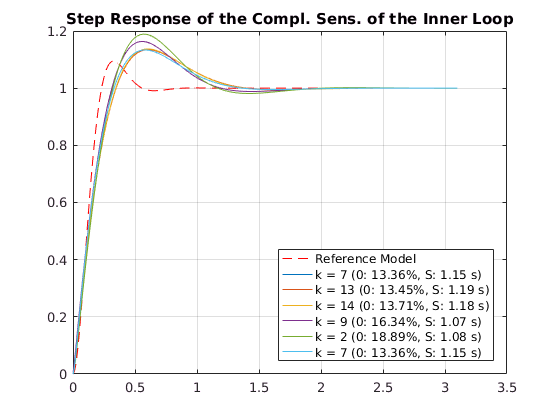


Tmax = max([ModelInfo.SettlingTime]) * 2;

figure() 
    [yref, t] = step(InnerReferenceModel_dt, Tmax);
    plot(t, yref, 'r--'); grid on; hold on;
    legend_entries = {'Reference Model'};
    
    ModelInfo = sortStruct(ModelInfo, 'StepOvershootPercent');
    for k = 1:3
        y = step(ModelInfo(k).ComplSens, t);
        legend_entries{end+1} = sprintf('k = %i (0: %.2f%%, S: %.2f s)', ... 
            ModelInfo(k).NoiseOrder, ModelInfo(k).StepOvershootPercent, ModelInfo(k).SettlingTime);
        plot(t, y);
    end
    
    ModelInfo = sortStruct(ModelInfo, 'SettlingTime');
    for k = 1:3
        y = step(ModelInfo(k).ComplSens, t);
        legend_entries{end+1} = sprintf('k = %i (0: %.2f%%, S: %.2f s)', ... 
            ModelInfo(k).NoiseOrder, ModelInfo(k).StepOvershootPercent, ModelInfo(k).SettlingTime);
        plot(t, y);
    end        
    
    title('Step Response of the Compl. Sens. of the Inner Loop');
    legend(legend_entries, 'Location', 'southEast');

Finally we can take a look a the results and things look pretty good. 